# Save Images to Image File

Instructions are in the task pane to the left. Complete and submit each task one at a time.

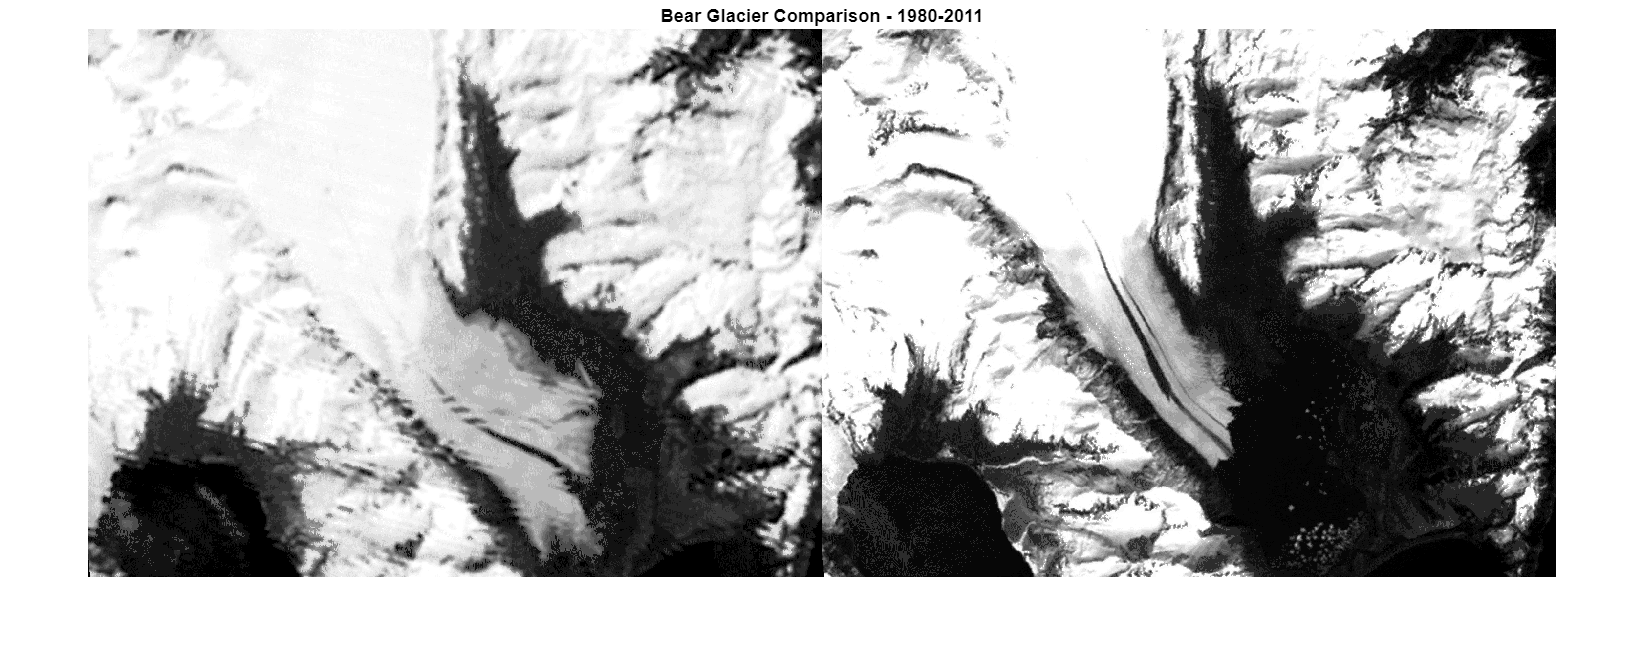

[glacier1980, map1980] = imread("./images/bearGlacier1980.png");
[glacier2011, map2011] = imread("./images/bearGlacier2011.png");

gs1980 = ind2gray(glacier1980, map1980);
gs2011 = ind2gray(glacier2011, map2011);

imshowpair(gs1980, gs2011, "montage")
title("Bear Glacier Comparison - 1980-2011")

## Task 1

You can save RGB and grayscale images with `imwrite`.

`imwrite``(``I``,``filename``)`

The filename is passed as a string or character vector.

imwrite(gs1980, "./images/gs1980.png")

## Task 2

imwrite(gs2011, "./images/gs2011.png")

Convert the indexed images to colormaps with two colors.

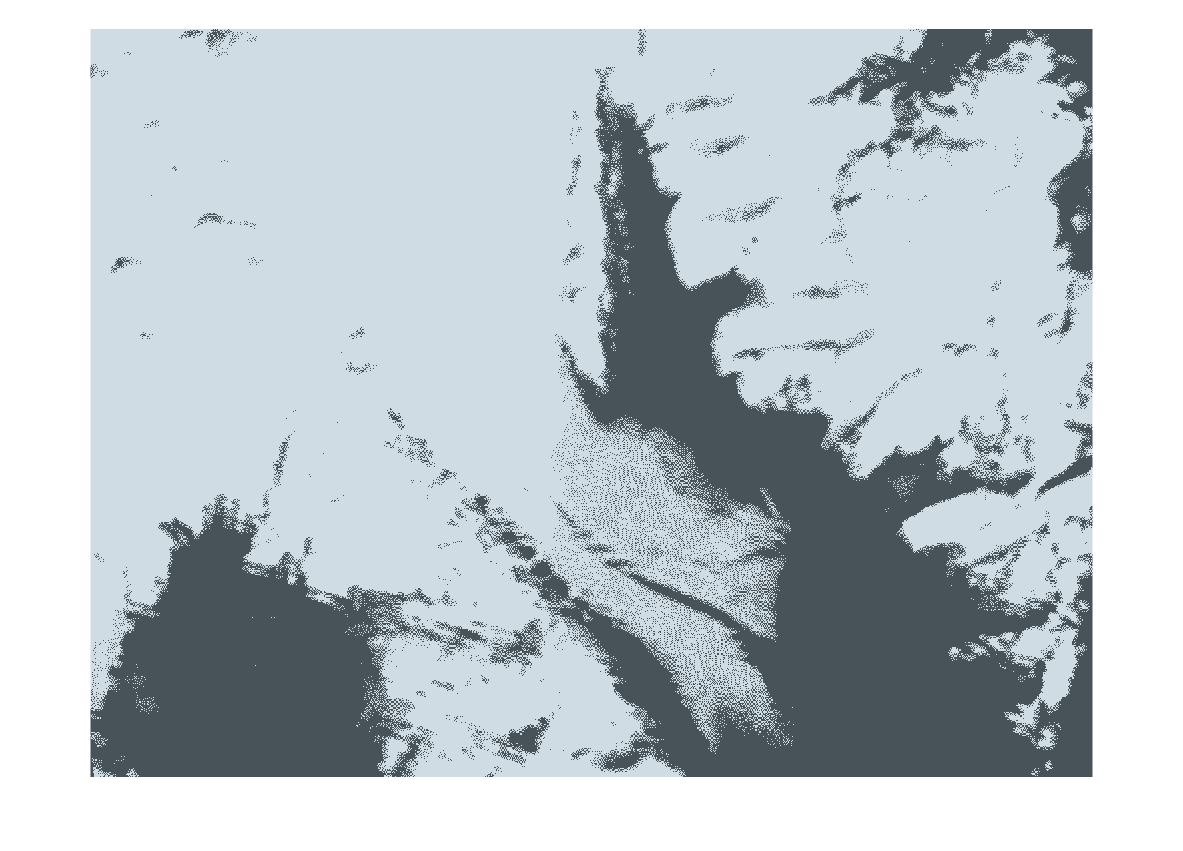

[ind1980, m2_1980] = imapprox(glacier1980, map1980,2);
imshow(ind1980, m2_1980)

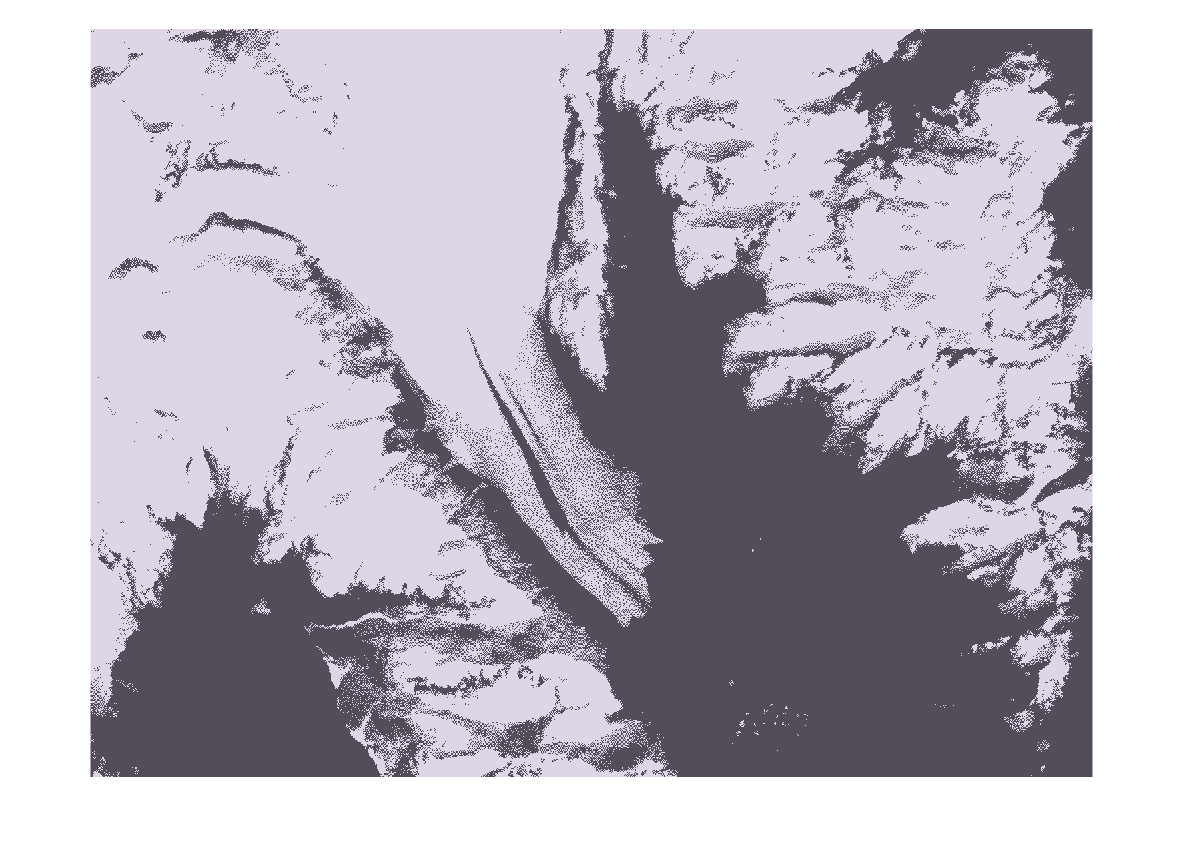


[ind2011, m2_2011] = imapprox(glacier2011, map2011,2);
imshow(ind2011, m2_2011)

## Task 3

In the script, the indexed images of the glaciers have been converted to indexed images with fewer colors.

You can also save indexed images with `imwrite` by passing the colormap in addition to the image and filename.

`imwrite``(``I``,``map``,``filename``)`

imwrite(ind1980, m2_1980, "./images/indGlacier1980.png")

## Task 4

imwrite(ind2011, m2_2011, "./images/indGlacier2011.png")